# **INTRODUCTION TO MATLAB FOR CONTROL SYSTEMS - LAB1B**

**Student Name:    Atta ul Wasay **

**H-ID:                    _ _ _ _ _ _ _ _ _ _ _ _ _ **

## **Objective**

To familiarize students with functions of MATLAB for Control Systems.

## Partial-Fraction Expansion

MATLAB has a command to obtain the partial-fraction expansion of $\frac{B\left(s\right)}{A\left(s\right)}$

Consider the transfer function

$\frac{B\left(s\right)}{A\left(s\right)}=\frac{\textrm{num}}{\textrm{den}}$ = $\frac{b_0 s^n +b_1 s^{n-1} +\;\ldotp \ldotp \ldotp \ldotp \ldotp b_n \;\;}{s^n +a_1 s^{n-1} +\;\ldotp \ldotp \ldotp \ldotp \ldotp a_n \;\;}$

In MATLAB row vectors num and den specify the coefficients of the numerator and denominator of the transfer function. That is,

`num = [b0 b1 . . . bn]`

`den = [1 a1 . . . an]`

The command

`[r, p, k] = residue(num, den)`

finds the residues, poles, and direct terms of a partial-fraction expansion of the ratio of two polynomials $B\left(s\right)$ and $A\left(s\right)$.

The partial-fraction expansion fo $\frac{B\left(s\right)}{A\left(s\right)}$ is given by


$$\frac{B\left(s\right)}{A\left(s\right)}=\frac{r\left(1\right)}{s-p\left(1\right)}+\frac{r\left(2\right)}{s-p\left(2\right)}+\;\ldotp \ldotp \ldotp \frac{r\left(n\right)}{s-p\left(n\right)}+k\left(s\right)\;$$


Comparing Equations, we note that $p\left(1\right)=-p_1 ,p\left(2\right)={-p}_2 \;\ldotp \ldotp \ldotp ,p\left(n\right)=-p_n ;\;r\left(1\right)\;=a_1 ,\;r\left(2\right)=a_2 \;\ldotp \ldotp \ldotp \ldotp r\left(n\right)=a_n$, [$k\left(s\right)$is a direct term.]

[Click here](https://www.mathworks.com/help/releases/R2020a/matlab/ref/residue.html) to have more information on [residue](http://www.mathworks.com) function.

### Example

Consider the following transfer function:


$$G\left(s\right)=\frac{s\;+2\;}{s^2 +7s+12}$$


% define numerator & denominator
num = [1 2];
den = [1 7 12];
tf(num, den)

ans =
 
      s + 2
  --------------
  s^2 + 7 s + 12
 
Continuous-time transfer function.
Model Properties


% find the coefficients of partial-fraction expansion
[r, p, k] = residue(num, den)

r =      2
    -1


p =     -4
    -3



k =

     []



### Task 

Find the partial-fraction expansion coefficients of the following transfer function. 

Create a symbolic variable $s$ and use the resultant coefficients to create a symbolic expression for the partial-fraction


$$G\left(s\right)=\frac{{2s}^3 \;+{5s}^2 +3s+6}{s^3 +{6s}^2 \;+\;11s+6}$$


% define numerator & denominator below
num = [2 5 3 6];
den = [1 6 11 6];
G = tf(num, den)

G =
 
  2 s^3 + 5 s^2 + 3 s + 6
  -----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties



% find the coefficients of partial-fraction expansion below
[r, p, k] = residue(num, den)

r =    -6.0000
   -4.0000
    3.0000


p =    -3.0000
   -2.0000
   -1.0000


k = 2

## Transient Response of a System

The transfer function of a system is represented by two arrays of numbers. 

Consider the following system


$$\frac{C\left(s\right)}{R\left(s\right)}=\frac{20}{s^2 +4s+20}$$


% Numerator & Denominator are defines as follows:
nc = 20;
dr = [1 4 20]

dr =      1     4    20



% tf function will create the transfer function model of the system
T = tf(nc, dr)

T =
 
        20
  --------------
  s^2 + 4 s + 20
 
Continuous-time transfer function.
Model Properties


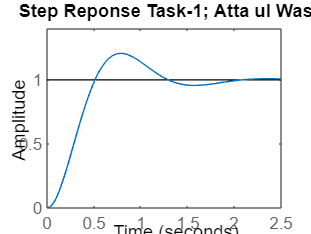


% Following function will generate plots of unit step response of the
% transfer function
step(T)     % double click on the plot to use plot features
title('Step Reponse Task-1; Atta ul Wasay')

stepinfo(T) % transient characteristics of sys

ans = struct with fields:
         RiseTime: 0.3452
    TransientTime: 1.8676
     SettlingTime: 1.8676
      SettlingMin: 0.9149
      SettlingMax: 1.2079
        Overshoot: 20.7866
       Undershoot: 0
             Peak: 1.2079
         PeakTime: 0.7829


More information on the `tf` function can be found [here](https://www.mathworks.com/help/releases/R2020a/control/ref/tf.html).

`step` function can take more than one arguments, e.g. in `step(sys,t)`, `t` is the user specified time

More information on the `step` function can be found [here](https://www.mathworks.com/help/releases/R2020a/control/ref/step.html).

### Task

Generate the unit step response of the following system with t = 0 to 50 with an increment of 0.1


$$\textrm{sys}=\frac{s^2 +2s+3}{s^4 +{1\ldotp 5s}^3 +{5s}^2 +6s+2}$$


**Note:**

- *Add Title to the plot*

- *Title must contain your name and H-ID*

% Define Numerator & Denominator below
num = [1 2 3];
den = [1 1.5 5 6 2];

% Define equally spaced vector for 't', below
t = 0:0.1:50;
% Create transfer function model of the system below
sys = tf(num, den)

sys =
 
           s^2 + 2 s + 3
  -------------------------------
  s^4 + 1.5 s^3 + 5 s^2 + 6 s + 2
 
Continuous-time transfer function.
Model Properties


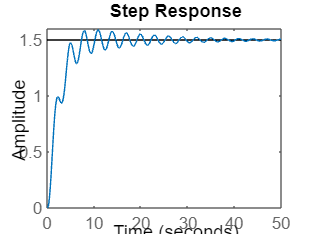

% Generate unit step response of the system using given time below
step(sys,t);


% determine the transient characteritics of the response
stepinfo(sys)

ans = struct with fields:
         RiseTime: 3.7962
    TransientTime: 27.5385
     SettlingTime: 27.5385
      SettlingMin: 1.2894
      SettlingMax: 1.5902
        Overshoot: 6.0117
       Undershoot: 0
             Peak: 1.5902
         PeakTime: 10.8355


## Don't forget

- to put your name at the beginning of the Live Script

- to save the Live Script to store the output

- to save the Live Script file as PDF

- to add your name & H-ID in the title of the each plot